# SimpleErrorAnalysis

Illustrates how to calculate experimental  (arthimetic) [mean](https://en.wikipedia.org/wiki/Mean), [rms](https://en.wikipedia.org/wiki/Root_mean_square), [variance](https://en.wikipedia.org/wiki/Variance),  [standard deviation](https://en.wikipedia.org/wiki/Standard_deviation) , and standard deviation of the mean of a sample of N measurements of some quantity x. Assuming the sample is derived from the normal distribution, the best estimate of the mean of the underlying probability distribution is the experimental mean. The experimental mean is expected to be itself normally distributed about the mean of the underlying probability distribution with a standard deviation best estimated as the experimental standard deviation divided by the square root of the number of measurements, significantly different number for large N, and is called the standard deviation of the mean or [standard error of the mean](https://en.wikipedia.org/wiki/Standard_error). The term 'error' is deprecated as it connotes a mistake when there is none. Nature makes no mistakes. 

Author: D. Carlsmith

## Create a row vector of measurements of a quantity x. Several ways are illustrated.

Create by hand. Fine for a few manual measurements of some quantity.

x0=[2.275, 2.350, 2.285, 2.320, 2.230, 2.295, 2.280, 2.300, 2.290, 2.350]

x0 =     2.2750    2.3500    2.2850    2.3200    2.2300    2.2950    2.2800    2.3000    2.2900    2.3500


N0=length(x0);

Create using indexing. Useful for testing.

N1=10;
x1=[1:N1]

x1 =      1     2     3     4     5     6     7     8     9    10


Create by generating a sample from a normal distribution. Useful for simulating. See [https://www.mathworks.com/help/stats/normrnd.html](https://www.mathworks.com/help/stats/normrnd.html) .

mu=5; sigma=2; N2=10;
x2= normrnd(mu, sigma,1, N2)

x2 =     4.1672    7.4494    4.9128    6.1648    2.9870    5.1290    6.2006    2.2770    5.6952    4.6363


Create by reading a csv, dat, txt, or xls and selecting a row or column. Useful for many manual measurements recorded in a file or spreadsheet program. First we make an array of random numbers and write it to a file. ,[https://www.mathworks.com/help/matlab/ref/readmatrix.html](https://www.mathworks.com/help/matlab/ref/readmatrix.html) 

Nrow=10;
Ncol=10;
M=normrnd(mu,sigma,Nrow,Ncol);
csvwrite('basic_matrix.csv',M)
M = csvread('basic_matrix.csv')

M =     3.1209    5.2204    1.7454    5.6357    7.1269    4.1813    2.2295    6.3801    6.5591    3.9702
    4.9249    6.5741    5.3327    5.2761    7.3138    4.6782    5.6210    6.1115    5.8788    3.2071
    1.2074    4.9955    5.7525    3.5785    5.1060    5.8187    4.5010    2.7595    4.8208    2.5935
    0.7440    5.1862    4.5461    6.5540    2.4232    3.0947    6.0075    1.9346    7.0424    7.0756
    2.6462    4.2437    2.7022    6.2448    4.2576    5.6346    3.2147    2.8043    3.2520    3.3081
    3.0189    2.0346    9.0487    6.2948    3.4844    5.1560    8.8170    2.1685    5.8294    4.6542
    2.6539    4.9124    0.2809    4.1487    3.8721    7.6488    5.2445    5.1191    5.6969    2.5827
    1.5491    6.9217    3.9801    7.0972    6.1103    4.5737    7.0941    4.1775    5.6985    4.4057
    5.5765    8.4765    2.3567    6.3214    3.8864    4.7310    4.5462    4.2640    3.5415   -1.4641
    1.8116    4.1396    3.7277   10.0180    3.2098    2.6573    4.6750    2.2781    5.6

Msize=size(M);
Nrow=Msize(1);
Ncol=Msize(2);

Pick some row and make a row vector.

row=2;
x3=M(row,:)

x3 =     4.9249    6.5741    5.3327    5.2761    7.3138    4.6782    5.6210    6.1115    5.8788    3.2071


N3=length(x3);

Pick some column and make a row vector.

col=3;
x4=M(:,col)'

x4 =     1.7454    5.3327    5.7525    4.5461    2.7022    9.0487    0.2809    3.9801    2.3567    3.7277


N4=length(x4);

## Compute mean, variance, rms,  standard deviation, and standard error of the mean. 

x=x2;
N=10;
xave=mean(x0)

xave = 2.2975

xvar=var(x0)

xvar = 0.0013

xrms=rms(x0)

xrms = 2.2978

xstd=std(x0)

xstd = 0.0359

xserr=xstd/N^(1/2)

xserr = 0.0114

Histogram measurements and fit to a normal distribution with [histfit.](https://www.mathworks.com/help/stats/histfit.html) 

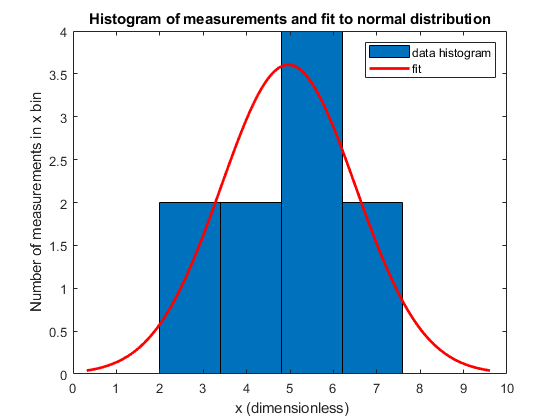

histfit(x)
title('Histogram of measurements and fit to normal distribution')
xlabel(' x (dimensionless)')
ylabel('Number of measurements in x bin')
legend('data histogram','fit')

`histfit` uses [fitdist](https://www.mathworks.com/help/stats/fitdist.html) to fit a distribution to data. Use `fitdist` to obtain parameters used in fitting. It requires a column vector x' not row vector x as its input.

pd = fitdist(x','Normal')

pd =   NormalDistribution

  Normal distribution
       mu = 4.96193   [3.85412, 6.06974]
    sigma = 1.54861   [1.06519, 2.82715]


The underlying probability distribution mean and standard deviation estimates are provided. The intervals next to the parameter estimates are the 95% [confidence intervals](https://en.wikipedia.org/wiki/68%E2%80%9395%E2%80%9399.7_rule) for the distribution parameters and correspond to the estimated mean plus or minus twice the standard deviation of the mean, not the standard deviation of the sample. In this example, the underlying probability distrbution had a mean of 5 and std of 2. The estimates of these parameters derived from the sample are consistent with the underlying values if they fall within the 95% confidence level intervals. If you run this Live Script 100 times, each time generating a different sample of 100 simulated measurements, you may expect to see consistency about 95 times and inconsistency about 5 times.